# Wavelets in the frequency domain

Copyright © 2018, Joël Karel, Maastricht University, Department of Data Science and Knowledge Engineering, All rights reserved

Wavelets filters act as low-pass and high-pass filters. We will investigate what is happening in this script.

## Single scale Haar wavelets

When performing a single scale haar wavelet decomposition, one deals with a single filter bank consisting of two filters.

## Haar low-pass filters

A low-pass filter which often is referred to as "scaling filter" and also "approximation filter", which in the case of the Haar wavelet has the filter coefficients [1/2,1/2].

We can then write the transfer function as:

H_0(z) = (1/2) + (1/2) z^(-1) = ((1/2) z + (1/2))/z

% transfer function system of low-pass filter
S_Hl=tf([1/2,1/2],[1,0],1)


S_Hl =
 
  0.5 z + 0.5
  -----------
       z
 
Sample time: 1 seconds
Discrete-time transfer function.



Since | `H_0(0)|=1, this is a low-pass filter.`

We can also look at the frequency response of this filter by plugging in z=e^{iw}, where w denotes frequency and using sinusoidal fidelity. Taking the frequencies from 0 to pi radians (recall: the rest is symmetrical and frequency pi radians corresponds to half the sampling frequency of the signal)

w=linspace(0,pi);

 We can plot the frequency response:

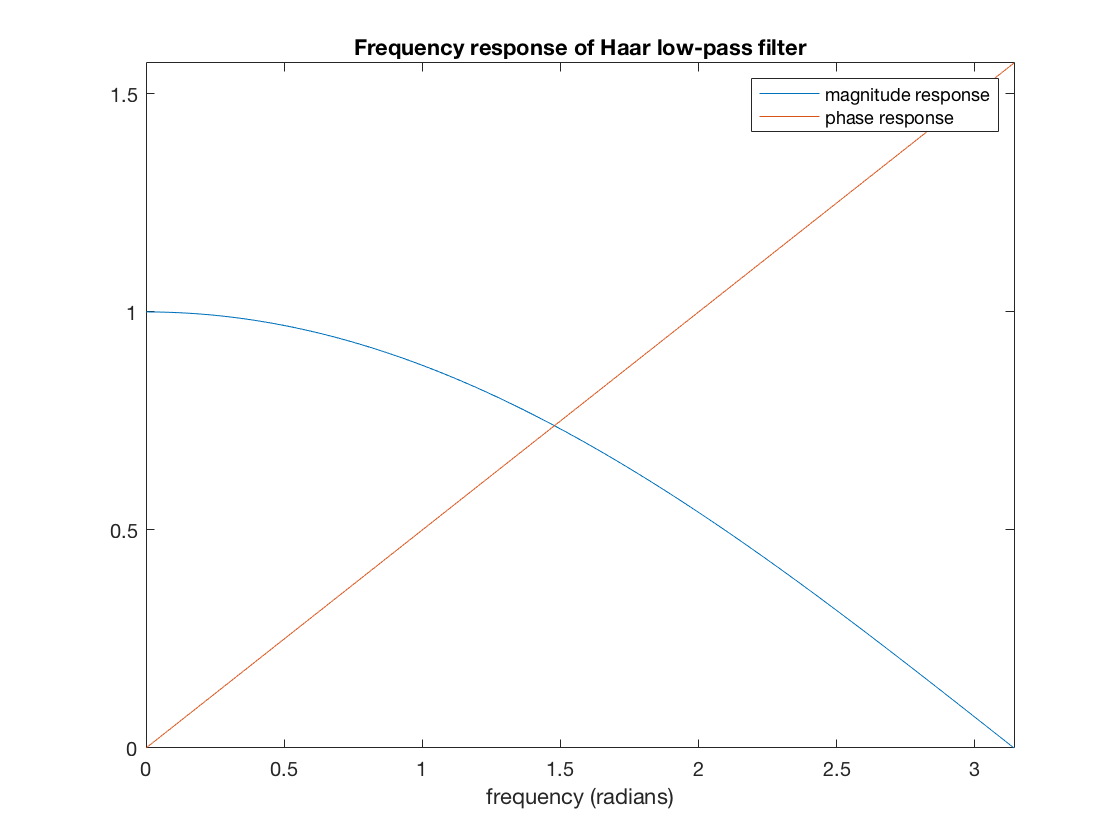

% compute frequency response of low-pass filter
Homega_Hl=0.5+0.5*exp(1i*w);
figure;
plot(w,abs(Homega_Hl),w,unwrap(angle(Homega_Hl),1));
legend({'magnitude response','phase response'})
title('Frequency response of Haar low-pass filter')
xlabel('frequency (radians)')
axis tight

Here you can again see that it is a low-pass filter indeed, though not a particular good one. 

We can investigate the effect of such a filter on a white noise signal:

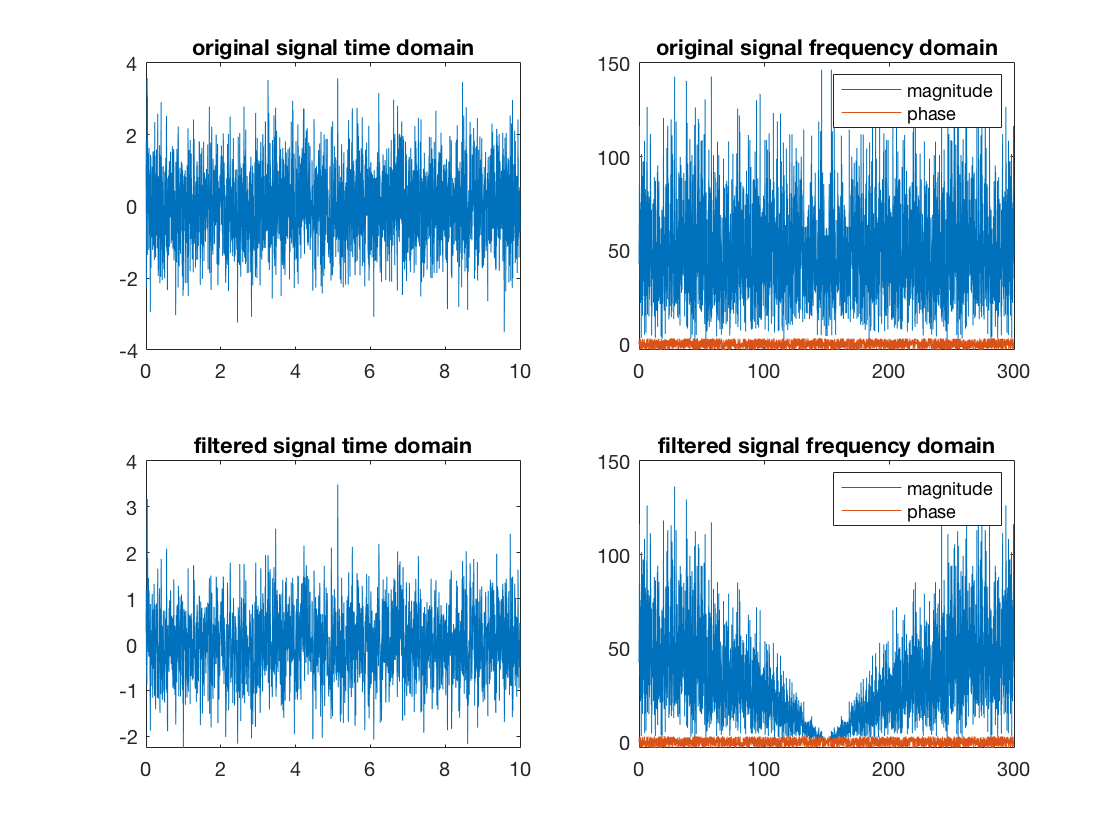

n=randn(3000,1); % let's say a 300Hz sampled signal
t=(1:3000)/300; % time vector
figure;
subplot(2,2,1)
plot(t,n);
title('original signal time domain')

N=fft(n); % Fourier transform of signal
f=linspace(0,300,3001);f(end)=[]; % frequencies
subplot(2,2,2)
plot(f,abs(N),f,angle(N));
legend({'magnitude','phase'});
title('original signal frequency domain')

% Now apply the filter
nf=filter([1/2,1/2],[1,0],n);
subplot(2,2,3)
plot(t,nf);
title('filtered signal time domain')

Nf=fft(nf); % Fourier transform of signal
subplot(2,2,4)
plot(f,abs(Nf),f,angle(Nf));
legend({'magnitude','phase'});
title('filtered signal frequency domain')

From this you can see that in the Fourier domain the Fourier transformed signal was, per frequency, multiplied with the frequency response of the filter. (sinusoidal fidelity)

Note that this kind of plots can be also obtained with Matlabs filter visualization tool fvtool. Here you can also see pole-zero plots, etc. 

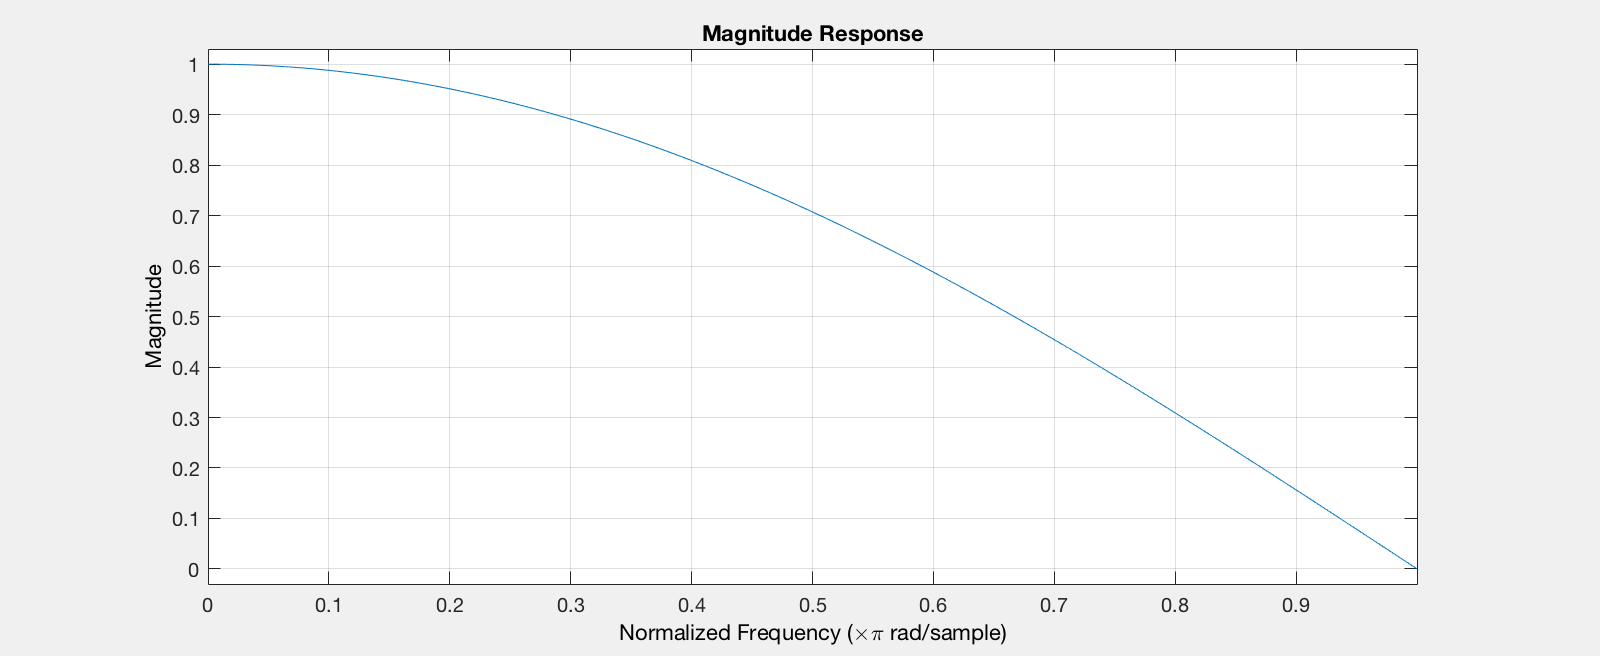

fvtool([1/2,1/2],[1,0])

## Haar high-pass filters

The high-pass filter works in a similar manner. It often is referred to as "wavelet filter" and also "detail filter", which in the case of the Haar wavelet has the filter coefficients [1/2,-1/2].

We can then write the transfer function as:

H_1(z) = (1/2) - (1/2) z^(-1) = ((1/2) z - (1/2))/z

Since H(0)=0, it clearly is a high-pass filter.

 We can plot the frequency response:

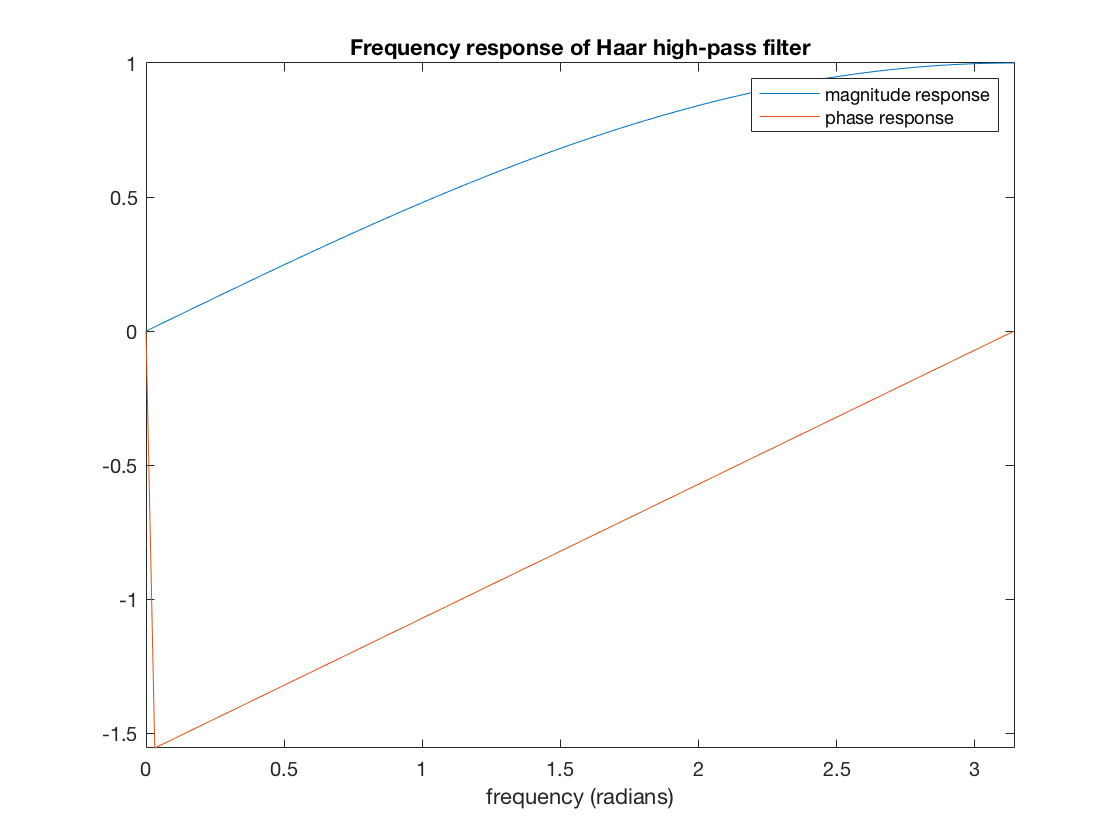

% compute frequency response of low-pass filter
Homega_Hh=0.5-0.5*exp(1i*w);
figure;
plot(w,abs(Homega_Hh),w,unwrap(angle(Homega_Hh),1));
legend({'magnitude response','phase response'})
title('Frequency response of Haar high-pass filter')
xlabel('frequency (radians)')
axis tight

## Power complementarity of the Haar filters

If we sum the absolute values squared of the frequency responses of the haar wavelets we get a joint frequency response that is a constant 1: the filter bank is an all-pass system.

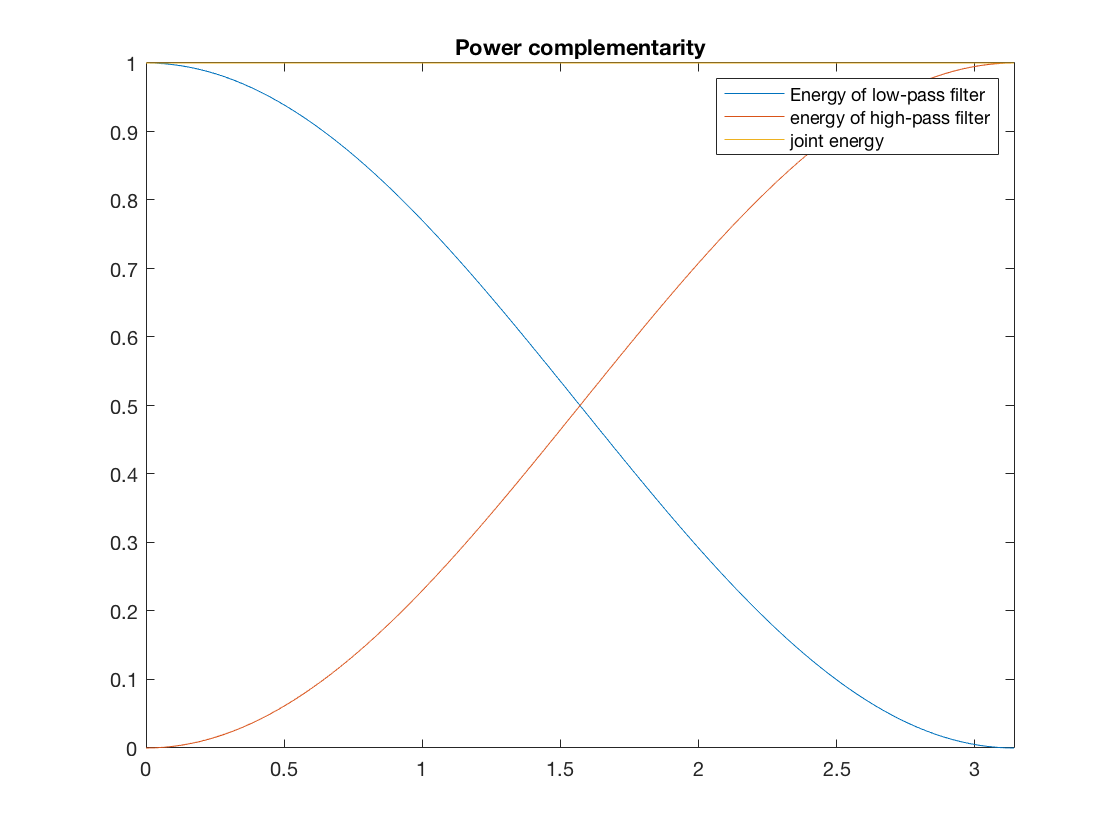

figure;
plot(w,abs(Homega_Hl).^2,w,abs(Homega_Hh).^2,w,abs(Homega_Hl).^2+abs(Homega_Hh).^2);
legend({'Energy of low-pass filter','energy of high-pass filter','joint energy'});
title('Power complementarity')
axis tight

## Multiresolution Haar - the effect of downsampling

Now, what is the effect of this downsampling? Let's look at a signal consisting of a 40 and 50Hz sinusoid and see what downsampling does on it.

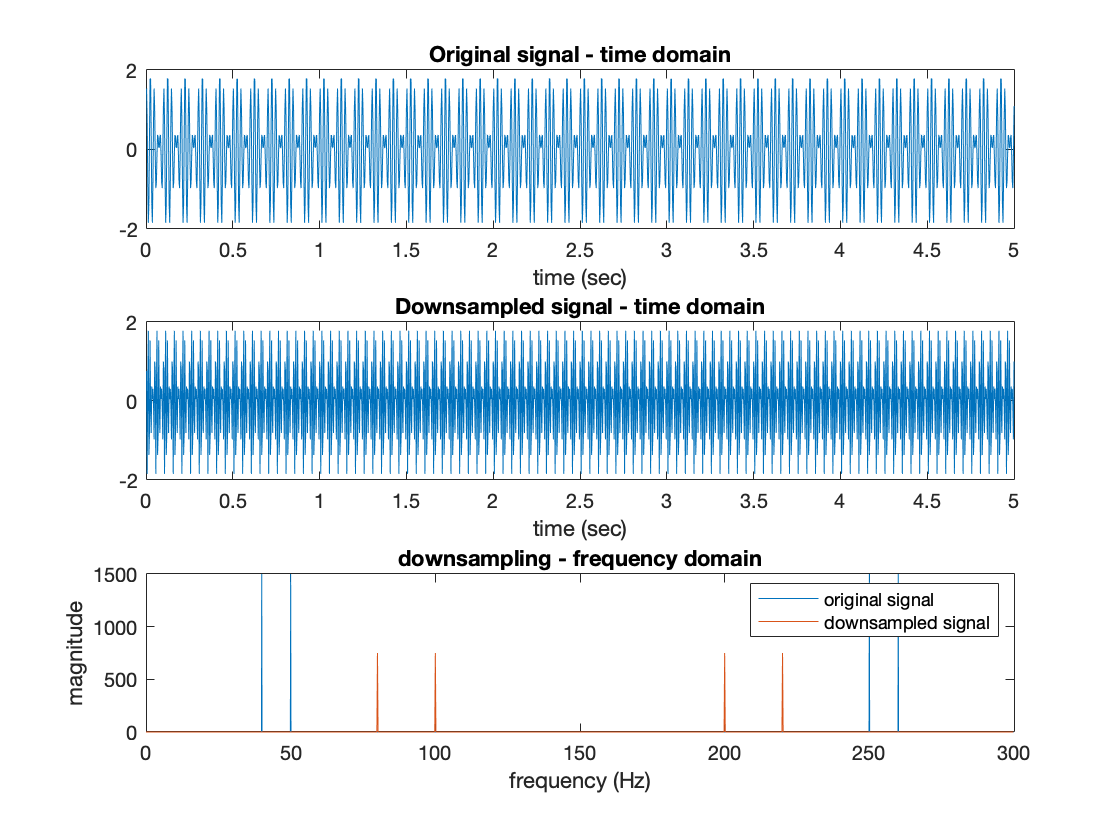

t=(1:3000)/300; % time vector
nf=sin(2*pi*t'*50)+cos(2*pi*t'*40); % signal with 40 and 50 Hz component
nfd=nf(2:2:end); % downsampled signal
td=(1:1500)/300; % time vector of downsampled signal

figure;
subplot(3,1,1)
plot(t,nf);
xlabel('time (sec)')
title('Original signal - time domain')
axis([0,5,-2,2])
subplot(3,1,2)
plot(td,nfd);
xlabel('time (sec)')
title('Downsampled signal - time domain')
axis([0,5,-2,2])

Nf=fft(nf); % Fourier transform of signal
f=linspace(0,300,3001);f(end)=[]; % frequencies
Nfd=fft(nfd); % Fourier transform of signal
fd=linspace(0,300,1501);fd(end)=[]; % frequencies
subplot(3,1,3)
plot(f,abs(Nf),fd,abs(Nfd))
xlabel('frequency (Hz)')
ylabel('magnitude')
legend({'original signal','downsampled signal'})
title('downsampling - frequency domain')

Here you can observe that downsampling stretches out the frequencies by a factor 2. This ensures that applying the filter bank again to the signal has an effect and effectively the high-pass filters act as band-pass filters.

## Daubechies wavelets

We can in the same way analyse the Daubechies wavelets.

H0db2=[1 1]/sqrt(2)

H0db2 =     0.7071    0.7071


H1db2=fliplr(H0db2).*[1 -1] % Haar high-pass (alternating flip)

H1db2 =     0.7071   -0.7071


H0db4=[(1+sqrt(3)) (3+sqrt(3)) (3-sqrt(3)) (1-sqrt(3))]/(4*sqrt(2)) % Haar low-pass

H0db4 =     0.4830    0.8365    0.2241   -0.1294


H1db4=fliplr(H0db4).*[1 -1 1 -1] % DB4 high-pass (alternating flip)

H1db4 =    -0.1294   -0.2241    0.8365   -0.4830


H0db6=(sqrt(2)/32)*[1+sqrt(10)+sqrt(5+2*sqrt(10)) 5+sqrt(10)+3*sqrt(5+2*sqrt(10)) 10-2*sqrt(10)+2*sqrt(5+2*sqrt(10)) 10-2*sqrt(10)-2*sqrt(5+2*sqrt(10)) 5+sqrt(10)-3*sqrt(5+2*sqrt(10)) 1+sqrt(10)-sqrt(5+2*sqrt(10))] % DB6 low-pass

H0db6 =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352


H1db6=fliplr(H0db6).*[1 -1 1 -1 1 -1] % DB6 high-pass (alternating flip)

H1db6 =     0.0352    0.0854   -0.1350   -0.4599    0.8069   -0.3327


We compute the frequency response and plot it

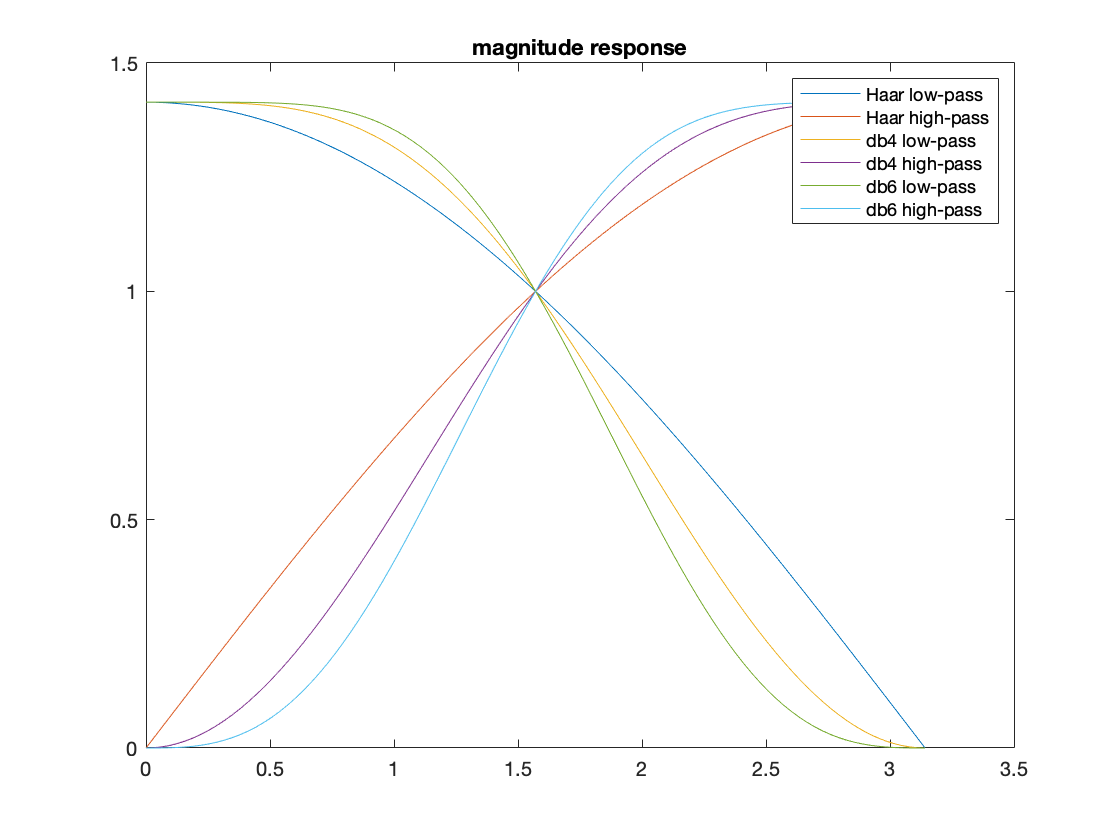

w = linspace(0,pi);
h20 = freqz(H0db2,[1 0],w); % frequency response calculated in lazy way
h21 = freqz(H1db2,[1 0],w);
h40 = freqz(H0db4,[1 0 0 0],w); % frequency response calculated in lazy way
h41 = freqz(H1db4,[1 0 0 0],w);
h60 = freqz(H0db6,[1 0 0 0 0 0],w); % frequency response calculated in lazy way
h61 = freqz(H1db6,[1 0 0 0 0 0],w);
figure;
plot(w,abs(h20),w,abs(h21),w,abs(h40),w,abs(h41),w,abs(h60),w,abs(h61))
legend({'Haar low-pass','Haar high-pass','db4 low-pass','db4 high-pass','db6 low-pass','db6 high-pass'});
title('magnitude response')